# QIBC analysis

YFP1: Geminin-venus (APC/C reporter) intensity

RFP1: mCherry nuclear intensity

FarRed2: EdU nuclear intensity

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C195_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%rows = [4 5];
conditions = {
    'DMSO 35',[1:4],3:5,1:37,'DMSO','35'; 
    'DMSO 36',[5:8],3:5,1:37,'DMSO','36'; 
    
    'DAB post 35',[1:4],6:8,1:37,'DAB post','35'; 
    'DAB post 36',[5:8],6:8,1:37,'DAB post','36';  
    
    'DAB pre 35',[1:4],9:11,1:37,'DAB pre','35'; 
    'DAB pre 36',[5:8],9:11,1:37,'DAB pre','36';  
    
    'unreleased 35',[1:4],2,1:37,'unreleased','35'; 
    'unreleased 36',[5:8],2,1:37,'unreleased','36';  
    
    'NR dox',[1:4],12,1:37,'NR','35'; 
    'R no dox',[5:8],12,1:37,'R','36'; 
    };

S = loadData_IF(conditions, dataDir);


**Compare dna**

conds = [8 10];

yval = 'dna';

gateVals = {'dna'};
rangeVals = {[2^19 2^21.5]}; 
data = {};

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(18,22,100);
    
    data = [data, {ydata}];

end
nhist(data,'samebins','noerror','pdf')

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


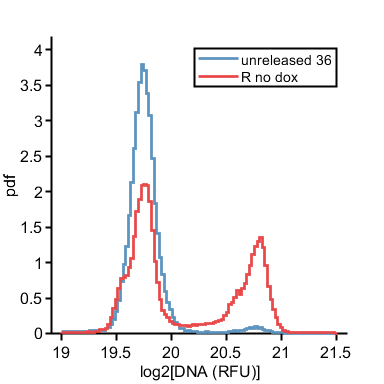

xlabel('log2[DNA (RFU)]')
legend(conditions(conds,1));
axis square
print_pdf([pwd() '\Figs\dnacompare.pdf'])

data

data = 1×2 cell array
    {52433×1 double}    {61472×1 double}


**Compare histograms of gem-venus**

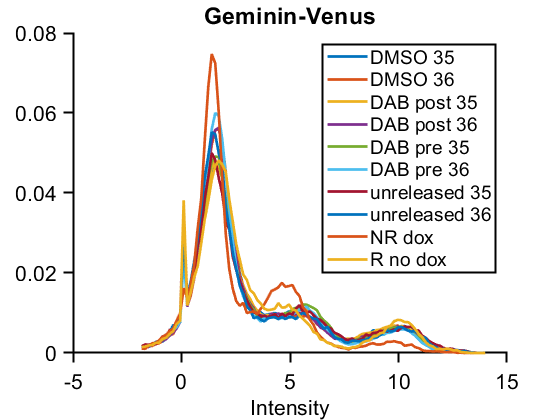

conds = [1 2 3 4 5 6 7 8 9 10];

yval = 'YFP1';

gateVals = {};
rangeVals = {[2^7 2^11]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(-2,14,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
xlabel('Intensity')
title('Geminin-Venus')
legend(conditions(conds,1));

hold off

**Compare histograms of mCherry**

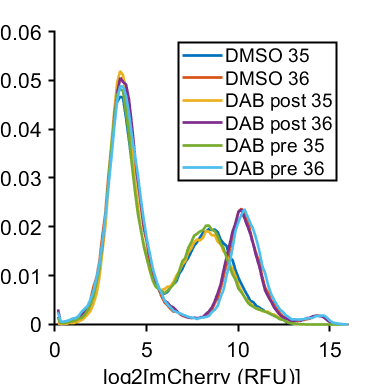

conds = [1 2 3 4 5 6];

yval = 'RFP1';

gateVals = {};
rangeVals = {[2^7 2^11]}; 

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    edges = linspace(0,16,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
axis square
legend(conditions(conds,1));
xlabel('log2[mCherry (RFU)]')
hold off
% title('mCherry')
set(gca,'FontSize',16)

**Load data into table**

conds=1:8;

dfTotal = table();

apclims = [2^8 2^20];
gateVals = {{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'},{'YFP1'}};
rangeVals = {{apclims},{apclims},{apclims},{apclims},{apclims},{apclims},{apclims},{apclims}};

for i=1:length(conds)
    ind = true(size(S(conds(i)).area));
    apc=S(conds(i)).YFP1(ind);
    edu=S(conds(i)).FarRed2(ind);
    sig=S(conds(i)).RFP1(ind);
    dna = S(conds(i)).dna(ind);
    
    gates = gateVals{i};
    for j=1:length(gates)
        gateData = S(conds(i)).(gates{j})(ind);
        %gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        apc = apc(inds);
        edu = edu(inds);
        sig = sig(inds);
        dna = dna(inds);
    end
    
    apc(apc<0.1) = 0.1;
    edu(edu<0.1) = 0.1;
    sig(sig<0.1) = 0.1;

    drugTreatment = repmat(categorical(conditions(conds(i),5)),numel(apc),1);
    constTreatment = repmat(categorical(conditions(conds(i),6)),numel(apc),1);
    
    dfTotal = [dfTotal;table(drugTreatment, constTreatment,apc,edu,sig)];
end

dfTotal.condition = categorical(strcat(string(dfTotal.constTreatment),{'\'},string(dfTotal.drugTreatment)));
dfTotal = movevars(dfTotal,'condition','After','constTreatment');
rubyEdges = [2^0 2^5 2^9 2^12];
dfTotal.rubyLevel = discretize(dfTotal.sig,rubyEdges,'categorical',{'no','low','high'});


order = {'35\unreleased','36\DMSO','36\DAB post','35\DMSO','35\DAB post'};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    inds = dfTotal.condition == order{i} & dfTotal.rubyLevel == 'high';

    data = (dfTotal.edu(inds));
    data(data < 2^6) = [];
    data = log2(data);
    if length(data) > 2000
        data = randsample(data,2000,false);
    end
    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * 0;
xkey = group_list(1:end-1) + offsetx(2:end);
n'

ans =         1120
        2000
        2000
        2000
        2000


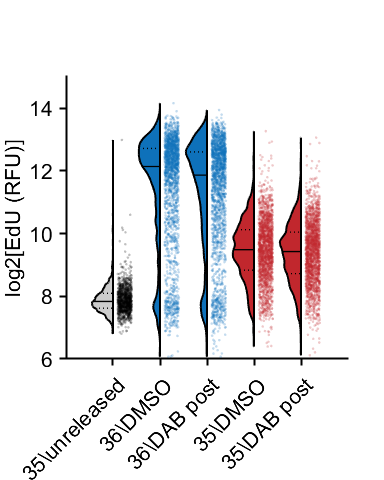

figure('Units', 'Inches', 'Position', [0, 0, 4, 5])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',order,'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
% cols = lines(2);
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 1 2 2 ],:)];


set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(1,:),cols(2,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('log2[EdU (RFU)]')
ylim([6 15])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\cdc6compare_alt_alt.pdf'])

% 
% figure,
% [~,~,stats] = anova1((ally),group,'off');
% cdc45PostHoc = multcompare(stats);

order = {'no dox','36\DMSO','35\DMSO'};
ally = [];
group = [];
rng(1)
for i=1:length(order)
    if i == 1
        data = S(10).RFP1(S(10).YFP1 > 2^8);
    else
            inds = dfTotal.condition == order{i};
    data = (dfTotal.sig(inds));
    end    
    data(data < 2^2) = [];
    data = log2(data);
    if length(data) > 2000
        data = randsample(data,2000,false);
    end
    ally = [ally; data];
    group = [group; i*ones(length(data),1)];
    n(i) = length(data);
end

n'

ans =         2000
        2000
        2000
        2000
        2000


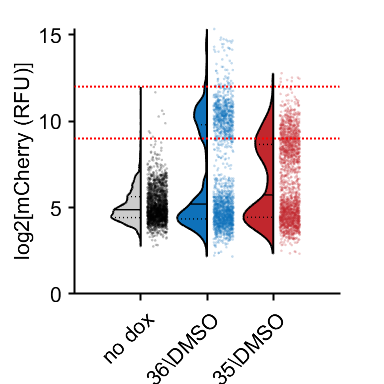

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',order);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
% cols = lines(2);
cols = [14 113 186; 193 39 45]/255;
groupcol = [0 0 0; cols([1 2 1 2 1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('log2[mCherry (RFU)]')
hline([9 12])
% ylim([6 15])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\cherrycompare_alt.pdf'])